# What should the basis functions be for fitting the raw tongue/lip signals?

Some fluorophores are present at different tissue layers.  The superficial layers (epithelial) contain FAD, NADH, and keratin in certain locations.  These are not going to be impacted by blood absorptions.  The blood is below the epithelial layer.

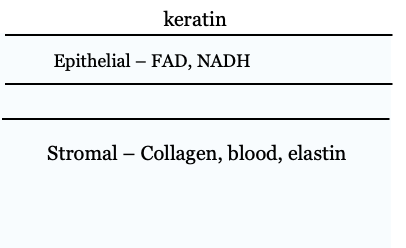

We have data about the excitations of each of these fluorophores.  These are in the isetfluorescence repository.  We are going to read them in and we are also going to read in some examples of raw data taken from our subjects' tongues and lips.  This script will explore how we might create basis functions to predict the raw data as weighted sums of the fluorophore excitations, but combining them as if some of the fluorophores are passing through blood.

The reason we think blood is necessary is because the raw data - directory spectral photometry measures from the tongue and lip - show some signs of the dips that are well known to be part of the blood absorbance (transmittance) measured in different contexts.

To support the calculations of absorbance and transmittance we created a Matlab class called 'medium', which helps us keep track of the relationship between absorbance, absorptance, transmittance and optical density.

## Programming notes

Repositories: isetcam, isetfluorescence and oe_tongue_lip

3/4 of the blood is oxygenated.  We might add in deoxy_ in the future.

## Initialize

Different analyses are based on different wavebands.

ieInit;
wave = 500:600;

## Load fluorophore emissions

We have many fluorophore files from the literature. These are analyzed in s_LoadFluorophoreMatrix.

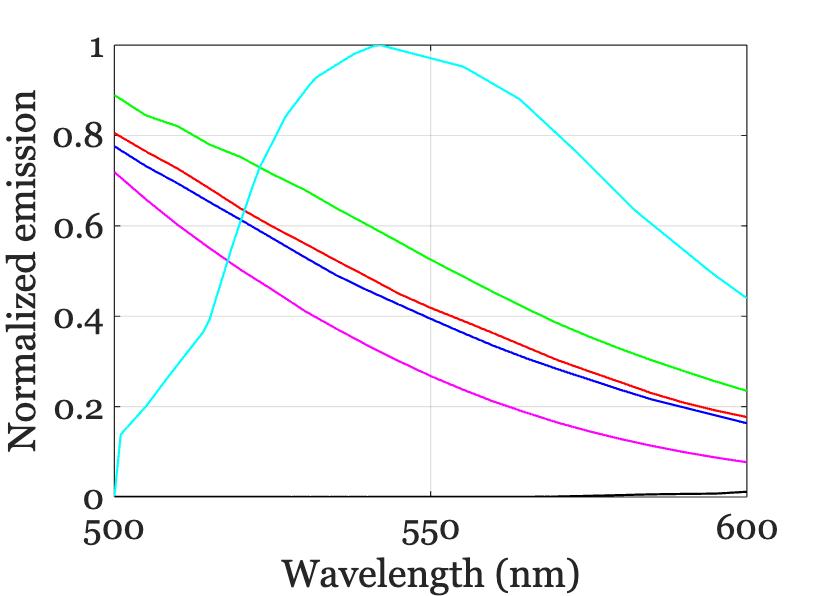

fluorophoreNames = {'CollagenWuQu','elastin_webfluor','KeratinWuQu',...
    'NADH_webfluor','FADBecker','protoporphyrin'};

[fluorophores,wave] = fiLoadBasis(fluorophoreNames,'wave',wave);

ieNewGraphWin;
plot(wave,fluorophores); grid on;
set(gca,'fontsize',16);
xlabel('Wavelength (nm)'); ylabel('Normalized emission')

## Read a couple of raw data sets

This is a database to find different files.

[T,dataDir] = oeDatabaseCreate;

We illustrate with Z's data because he has little porphyrin. 

These are measurements with different excitation lights at max intensity.  All the subjects show the peak shift from 500 to 515 as the excitation light changes from 405 to 450.

Also, notice the very large dip on the lip around 580, but not on the tongue. 

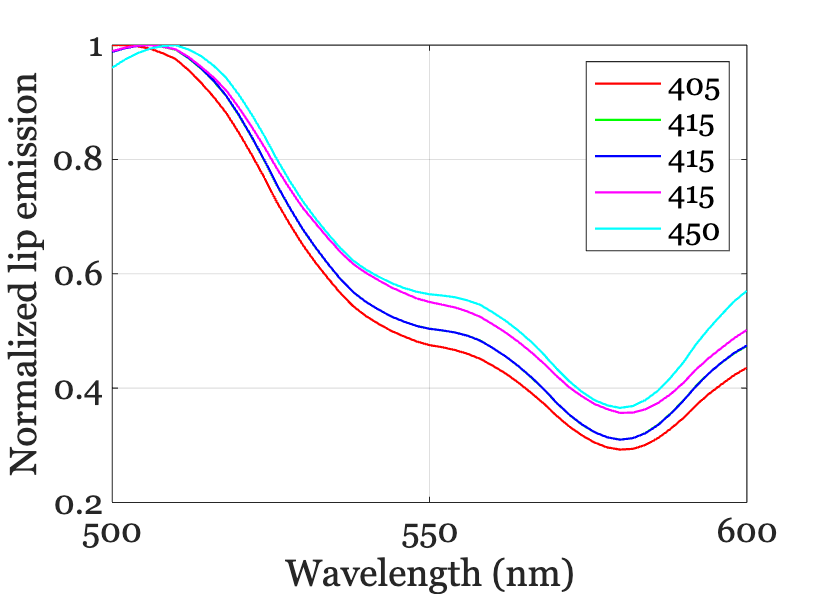

files405 = ieTableGet(T,'subject','Z','substrate','lip','e wave',405,'e level',980);
files415 = ieTableGet(T,'subject','Z','substrate','lip','e wave',415,'e level',910);
files450 = ieTableGet(T,'subject','Z','substrate','lip','e wave',450,'e level',870);
lipFiles = cat(1,files405,files415,files450);

lipData = zeros(numel(wave),numel(lipFiles));

ieNewGraphWin;
for ii=1:numel(lipFiles)
    data = ieReadSpectra(fullfile(dataDir,lipFiles{ii}),wave); 
    lipData (:,ii) = data(:);
    plot(wave,data/max(data(:))); hold on;
end
legend({'405','415','415','415','450'});
xlabel('Wavelength (nm)'); ylabel('Normalized lip emission'); grid on;

ieNewGraphWin;

files405 = ieTableGet(T,'subject','Z','substrate','tongue','e wave',405,'e level',980)

files405 = 2×1 string array
    "spd-2024-03-14-Z-405nm_tongue_980mA-1.mat"
    "spd-2024-03-14-Z-405nm_tongue_980mA.mat"


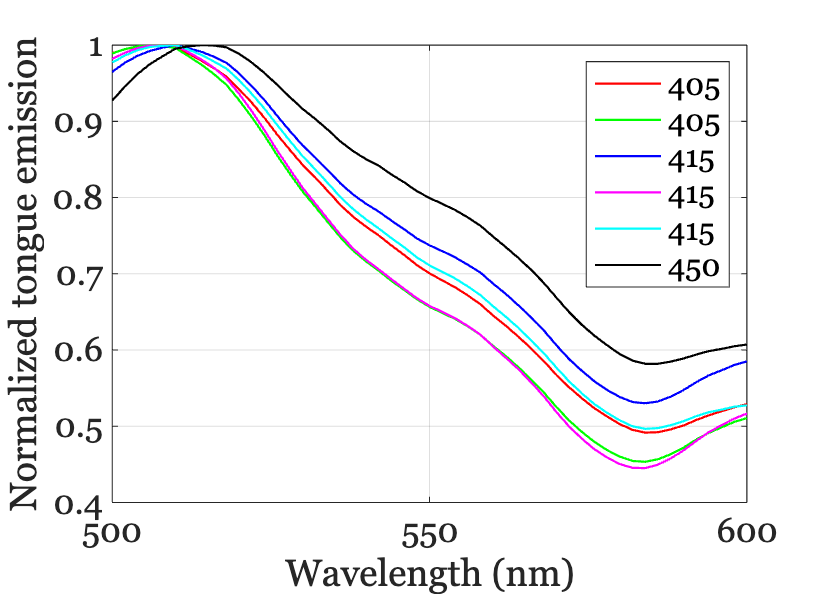

files415 = ieTableGet(T,'subject','Z','substrate','tongue','e wave',415,'e level',910);
files450 = ieTableGet(T,'subject','Z','substrate','tongue','e wave',450,'e level',870);
tongueFiles = cat(1,files405,files415,files450);
tongueData = zeros(numel(wave),numel(tongueFiles));

for ii=1:numel(tongueFiles)
    data = ieReadSpectra(fullfile(dataDir,tongueFiles{ii}),wave); 
    tongueData (:,ii) = data(:);
    plot(wave,data/max(data(:))); hold on;
end
legend({'405','405','415','415','415','450'});
xlabel('Wavelength (nm)'); ylabel('Normalized tongue emission')
grid on;

## Select and combine the fluorophores for a basis

First, let's make a large number of basis functions from the fluorophores and the fluorophores modified by blood.  Let's make sure that we can get very close to the raw data when they are overfit this way.

We will make a list of all the fluorophore emissions in a matrix.  This could become a function, such as

First, check that the full matrix can predict the data samples.  We think it won't without (a) accounting for blood, and (b) adding some more.  The formula is simple for the full linear calculation


$$d=\textrm{Fw}$$


This is the completely free method for estimating.

## Lips

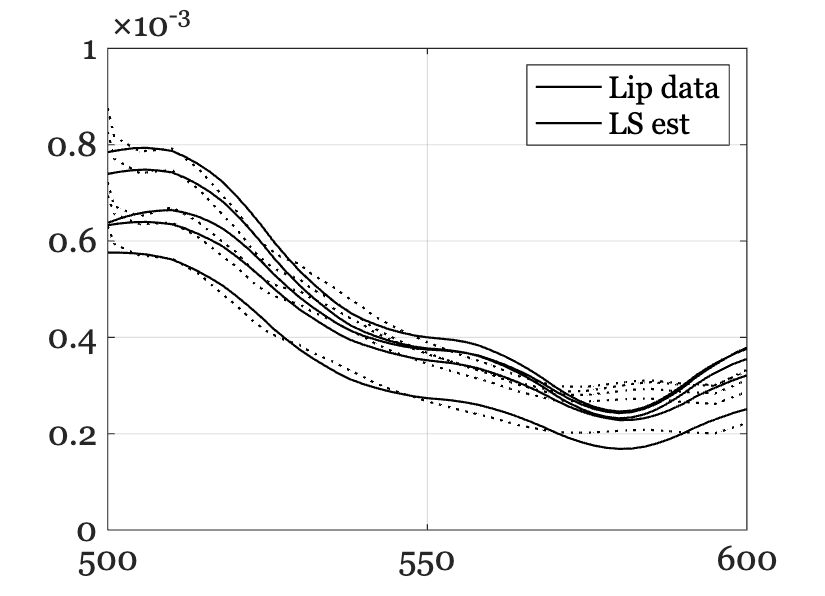

wgtsLS = pinv(fluorophores)*lipData;

ieNewGraphWin;
plot(wave,lipData,'k-',wave,fluorophores*wgtsLS,'k:');
grid on;
legend({'Lip data','LS est'});

This is non-negative method for estimating.  In both cases, the little wavy part misses where the blood absorbance may matter.  In the next section we will put some blood absorbance into certain fluorophores to see if we improve the fit.  

Also, the increase starting around 600 matches the rise of the porphyrins.

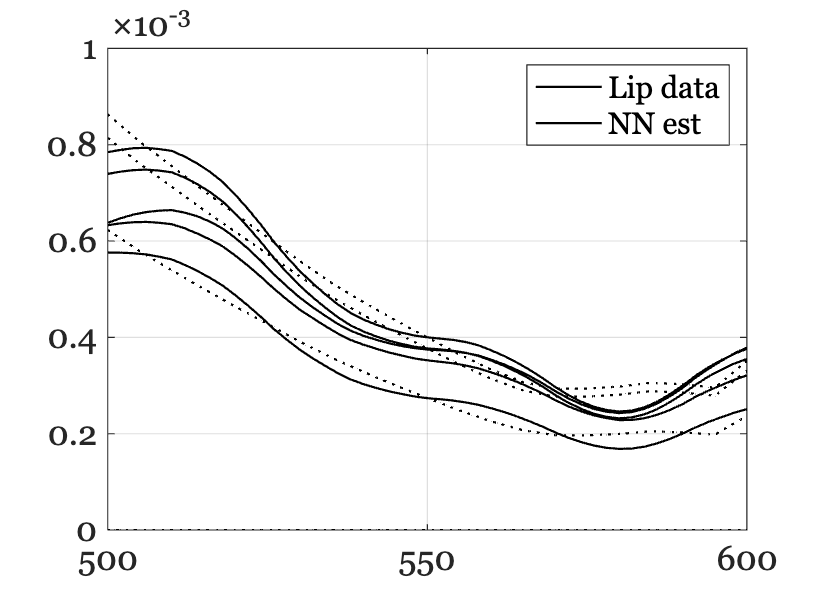

wgtsNN = zeros(size(wgtsLS));
% lambda = 10^-9;
for dd = 1:3
    wgtsNN(:,dd) = lsqnonneg(fluorophores,lipData(:,dd));
    % wgtsNN(:,dd) = lasso(fluorophores, lipData(:,dd), 'Lambda', lambda);    
end

ieNewGraphWin;
plot(wave,lipData,'k-',wave,fluorophores*wgtsNN,'k:');
grid on;
legend({'Lip data','NN est'});

## Tongue

Least squares

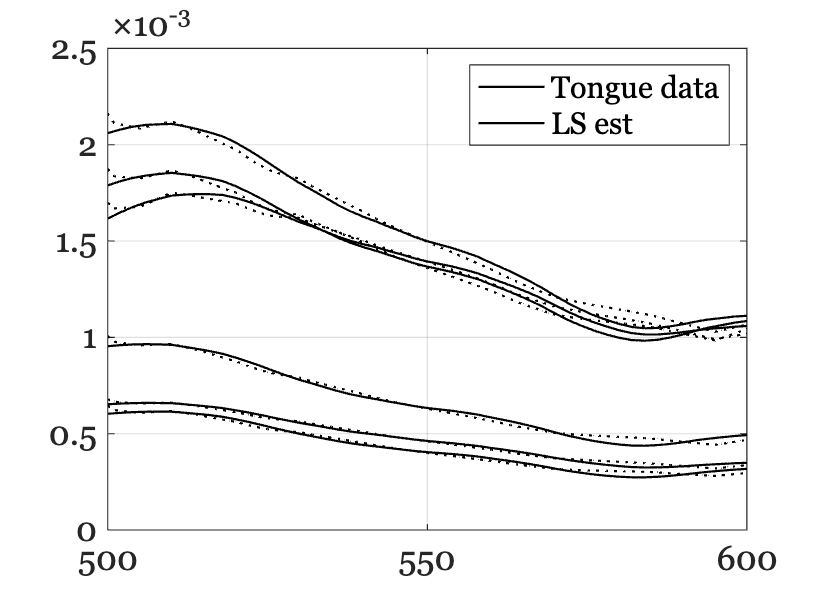

    {'CollagenWuQu'    }
    {'elastin_webfluor'}
    {'KeratinWuQu'     }
    {'NADH_webfluor'   }
    {'FADBecker'       }
    {'protoporphyrin'  }

    0.0011    0.0015    0.0032    0.0008    0.0027    0.0023
    0.0009    0.0019    0.0035    0.0018    0.0042    0.0038
   -0.0002   -0.0010   -0.0012   -0.0013   -0.0011   -0.0002
   -0.0012   -0.0016   -0.0040   -0.0009   -0.0041   -0.0048
   -0.0001   -0.0002   -0.0003   -0.0002   -0.0004   -0.0002
    0.0076    0.0104    0.0243    0.0062    0.0205    0.0186



wgtsLS = pinv(fluorophores)*tongueData;

ieNewGraphWin;
plot(wave,tongueData,'k-',wave,fluorophores*wgtsLS,'k:');
grid on;
legend({'Tongue data','LS est'}); disp(fluorophoreNames'); disp(wgtsLS);

**This is non-negative method for estimating**

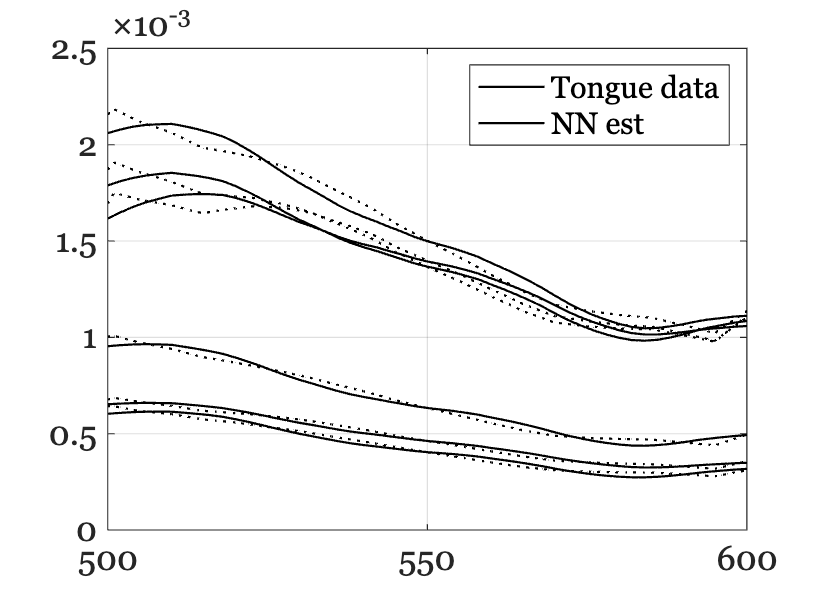

wgtsNN = zeros(size(fluorophores,2),size(tongueData,2));

for dd = 1:size(tongueData,2)
    wgtsNN(:,dd) = lsqnonneg(fluorophores,tongueData(:,dd));
end

ieNewGraphWin;
plot(wave,tongueData,'k-',wave,fluorophores*wgtsNN,'k:');
grid on;
legend({'Tongue data','NN est'});

disp(fluorophoreNames'); disp(wgtsNN);

    {'CollagenWuQu'    }
    {'elastin_webfluor'}
    {'KeratinWuQu'     }
    {'NADH_webfluor'   }
    {'FADBecker'       }
    {'protoporphyrin'  }

    0.0008    0.0009    0.0023    0.0002    0.0020    0.0020
         0    0.0003         0    0.0006    0.0006    0.0001
         0         0         0         0         0         0
         0         0         0         0         0         0
    0.0001    0.0001    0.0004    0.0000    0.0004    0.0005
    0.0137    0.0191    0.0452    0.0114    0.0420    0.0430



## Read in the oxy data

Let's amend the fluorophore basis by adding in collagen and elastin after some filtering by blood.  Notice that the blood has the two characteristic dips at 540 nm and 580nm.  We see little bumps like that in the raw data (above).

For different purposes we might choose different wavebands.  The raw data are pretty much good from 500-670 or so.  The wavelengths above 600 nm are mainly porphyrin fluorescence (bacteria on the tongue).

We only consider oxygenated blood now because 100% of the blood from the heart lung is oxygenated, and about 50% of the blood in the veins is also oxygenated. 

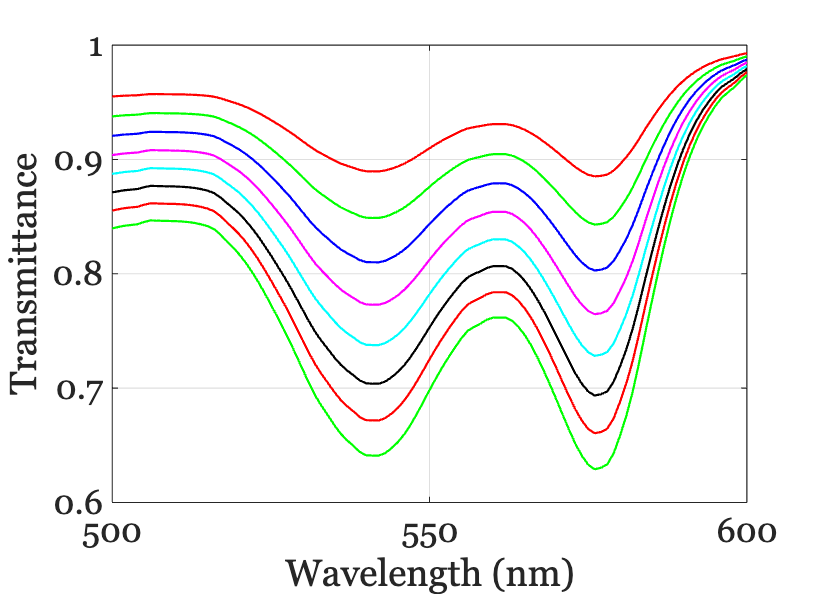

oxyblood = medium('oxy_molarExtinctionCoefficient.mat','wave',wave);

ieNewGraphWin;
for od = (0.5:0.2:2)
    oxyblood.opticalDensity = od;
    plot(wave,oxyblood.transmittance); hold on;
end
grid on; xlabel('Wavelength (nm)'); ylabel('Transmittance');

## Augment the fluorophores

This should also become a function that takes a fluorophore and modifies it by blood transmittance with some arguments.

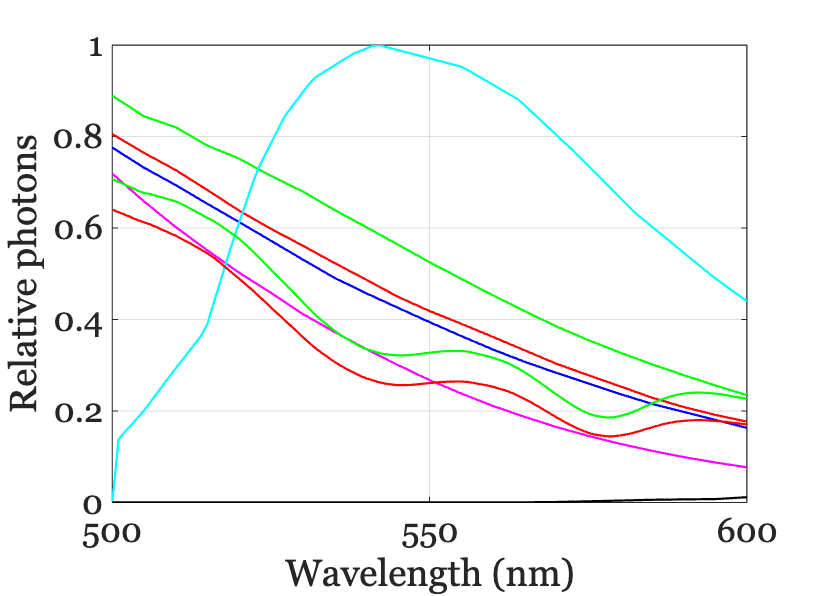

collagenF = fiReadFluorophore('CollagenWuQu');
collagen = fluorophoreGet(collagenF,'normalized emission','wave',wave);

elastinF = fiReadFluorophore('elastin_webfluor');
elastin  = fluorophoreGet(elastinF,'normalized emission','wave',wave);

oxyblood.opticalDensity = 2.5;
transmittance = oxyblood.transmittance;
collagenO = collagen(:) .* transmittance(:);
elastinO = elastin(:) .* transmittance(:);

fluorophoresO = [fluorophores, collagenO(:), elastinO(:)];
ieNewGraphWin;
plot(wave,fluorophoresO);
xlabel('Wavelength (nm)'); ylabel('Relative photons'); grid on;

**Tongue: non-negative **

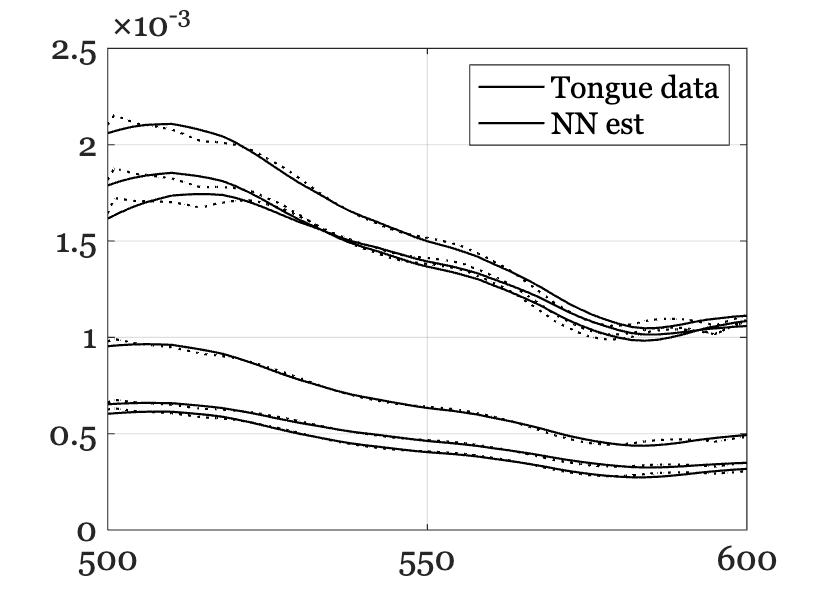

wgtsNN = zeros(size(fluorophoresO,2),size(tongueData,2));

for dd = 1:size(tongueData,2)
    wgtsNN(:,dd) = lsqnonneg(fluorophoresO,tongueData(:,dd));
end

ieNewGraphWin;
plot(wave,tongueData,'k-',wave,fluorophoresO*wgtsNN,'k:');
grid on;
legend({'Tongue data','NN est'});

disp(fluorophoreNames'); disp(wgtsNN);

    {'CollagenWuQu'    }
    {'elastin_webfluor'}
    {'KeratinWuQu'     }
    {'NADH_webfluor'   }
    {'FADBecker'       }
    {'protoporphyrin'  }

         0         0         0         0         0         0
    0.0003    0.0004    0.0006    0.0003    0.0010    0.0005
         0         0         0         0         0         0
         0         0         0         0         0         0
    0.0001    0.0002    0.0005    0.0001    0.0005    0.0007
    0.0095    0.0120    0.0314    0.0069    0.0279    0.0302
    0.0006    0.0004    0.0019         0    0.0014    0.0019
         0    0.0005    0.0001    0.0005    0.0005         0



**Lip: non-negative with oxygen**

wgtsNN = zeros(size(fluorophoresO,2),size(lipData,2));

for dd = 1:size(lipData,2)
    wgtsNN(:,dd) = lsqnonneg(fluorophoresO,lipData(:,dd));
end

ieNewGraphWin;
cols = [1 2 3 4 5]

cols =      1     2     3     4     5


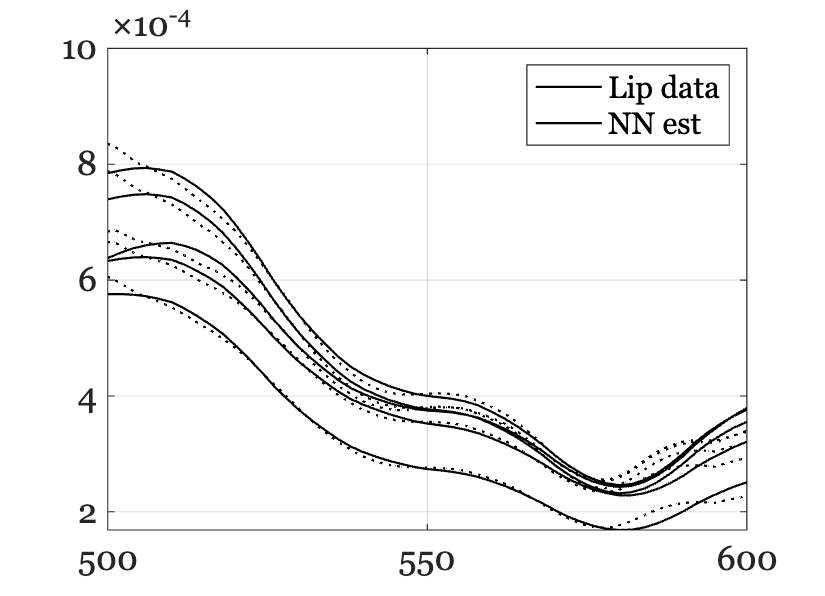

plot(wave,lipData(:,cols),'k-',wave,fluorophoresO*wgtsNN(:,cols),'k:');
grid on;
legend({'Lip data','NN est'});

disp(fluorophoreNames'); disp(wgtsNN);

    {'CollagenWuQu'    }
    {'elastin_webfluor'}
    {'KeratinWuQu'     }
    {'NADH_webfluor'   }
    {'FADBecker'       }
    {'protoporphyrin'  }

         0         0         0         0         0
         0         0         0    0.0001         0
         0         0         0         0         0
    0.0002    0.0002    0.0002    0.0001    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0001
    0.0052    0.0073    0.0068    0.0069    0.0085
         0         0         0         0         0
    0.0006    0.0010    0.0009    0.0007    0.0009

